addpath("backend/")

% Das folgende Skript findet die Einsetzposition von Puzzleteilen,
% dafür benötigt es ein Bild "lose" liegender Teile und ein Bild des
% beendeten Puzzles.
% Jeder Abschnitt hat einstellbare Parameter und kann (wenn das Skript 1x
% vollständig durchlaufen ist) in Isolation ausgeführt werden.

% Durch verändern der image Variable kann eins der hinterlegten
% Beispielbilder ausgewählt werden.
image = 4

image = 4

switch image
case 1
    piecesRGB = im2double(imread("images/puzzle/pieces_clean.png"));
    finishedRGB = im2double(imread("images/puzzle/pirate_puzzle.jpg"));
case 2
    piecesRGB = im2double(imread("images/puzzle/pirate_pieces_04.jpg"));
    piecesRGB = imcrop(piecesRGB, [800,3600,700,700]);
    finishedRGB = im2double(imread("images/puzzle/pirate_puzzled_03.jpg"));
case 3
    piecesRGB = im2double(imread("images/puzzle/spongebob_pieces_clean.png"));
    finishedRGB = im2double(imread("images/puzzle/spongebob_full_clean.jpg"));
case 4
    piecesRGB = im2double(imread("images/puzzle/spongebob_pieces_bright.jpg"));
    piecesRGB = imcrop(piecesRGB, [2000,0,1200,1200]);
    finishedRGB = im2double(imread("images/puzzle/spongebob_full.jpg"));
end

piecesGray = rgb2gray(piecesRGB)

piecesGray =     0.5887    0.6034    0.5799    0.6034    0.6701    0.7093    0.7132    0.6975    0.6818    0.7015    0.6897    0.6818    0.6701    0.6544    0.6348    0.6230    0.6191    0.5917    0.6152    0.6466    0.6662    0.6701    0.6662    0.6637    0.6637    0.6558    0.6598    0.6676    0.6715    0.6755    0.6676    0.6515    0.6358    0.6300    0.6104    0.6339    0.6770    0.6653    0.6104    0.6064    0.6496    0.6613    0.6260    0.6104    0.6260    0.6378    0.6300    0.6300    0.6457    0.6359
    0.6088    0.5995    0.5838    0.6152    0.6701    0.6936    0.6936    0.6897    0.6858    0.7054    0.6897    0.6818    0.6779    0.6622    0.6348    0.6113    0.6034    0.6074    0.6387    0.6701    0.6701    0.6466    0.6387    0.6598    0.6833    0.6637    0.6715    0.6794    0.6872    0.6833    0.6755    0.6593    0.6476    0.6457    0.6378    0.6417    0.6535    0.6496    0.6300    0.6378    0.6613    0.6613    0.6300    0.6143    0.6260    0.6300    0.6221    0.6221    0.

% In diesem Abschnitt wird eine Maske mit Labeln erstellt, um die
% Puzzleteile im Bild mit dem losen Teilen zu separieren.
% Grob: die Maske wird aus einem Kantenbild generiert, wobei der Hintergrund
% mittels Flood Fill bis zu den Kanten gefüllt wird. Das Kantenbild als
% Basis hat den Vorteil der Robustheit gegenüber Beleuchtungsunterschieden.
% Eine Segmentierung mittels ML würde vermutlich noch robustere Ergebnisse
% erzielen, allerdings fehlt es uns an entsprechenden Trainingsdaten.
%
% Anmerkung: der Flood Fill Algorithmus beginnt immer bei Koordinate (1 1),
% daher muss darauf geachtet werden, dass an dieser Position keine Kante
% erkannt wird.

% Treshold zur Kantenerkennung, erhöhen, falls zu viele Kanten gefunden
% werden (zum Beispiel bei einem starken Muster im Hintergrund).
cannyTresh = 0.14

cannyTresh = 0.1400

% Glättung des Kantenbildes, erhöhen bei unterbrochenen Kanten.
gaussSigma = 2

gaussSigma = 2

% Zusammenhängende Flächen in der Maske die weniger als minAreaSize Pixel
% groß sind werden entfernt, anpassen je nach Auflösung.
minAreaSize = 1000

minAreaSize = 1000

% Wie stark Ränder von Flächen in der Maske erodiert werden sollen, um eine
% Aufweichung der Kanten durch die Gauß Klättung zu verhindern.
erodeRadius = 5

erodeRadius = 5

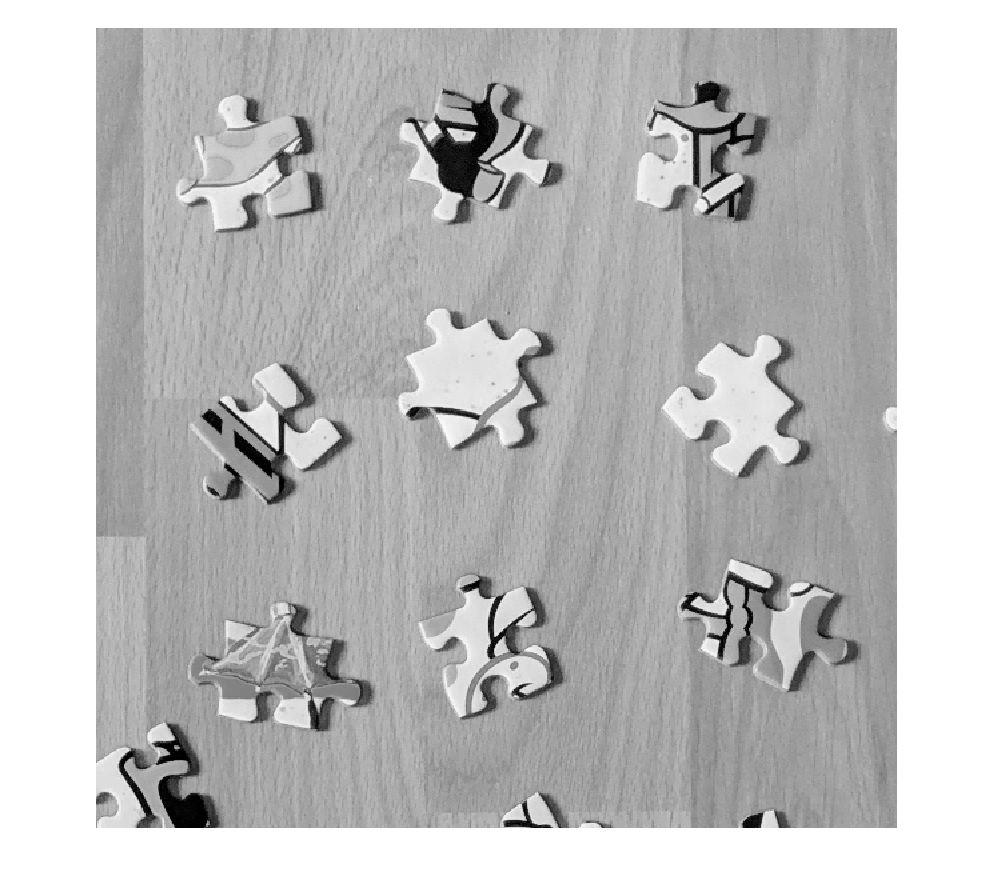


mask = piecesGray;
imshow(mask)

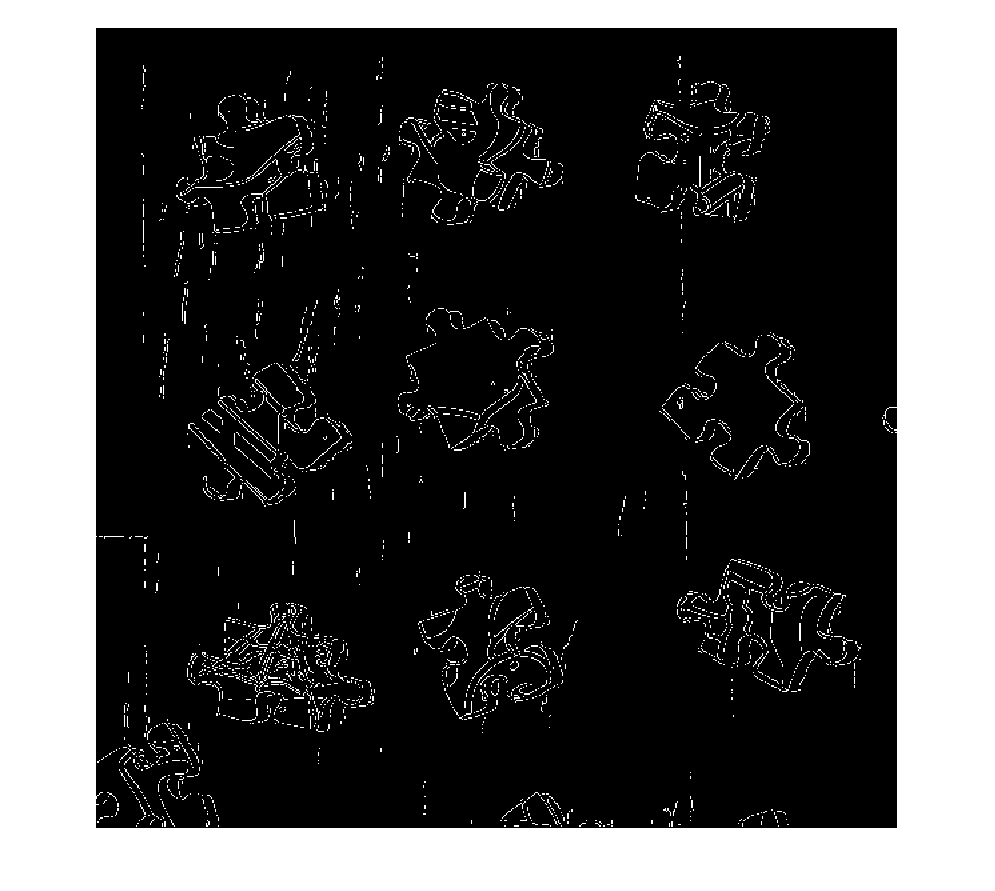

mask = edge(mask, 'canny', cannyTresh);
imshow(mask, [])

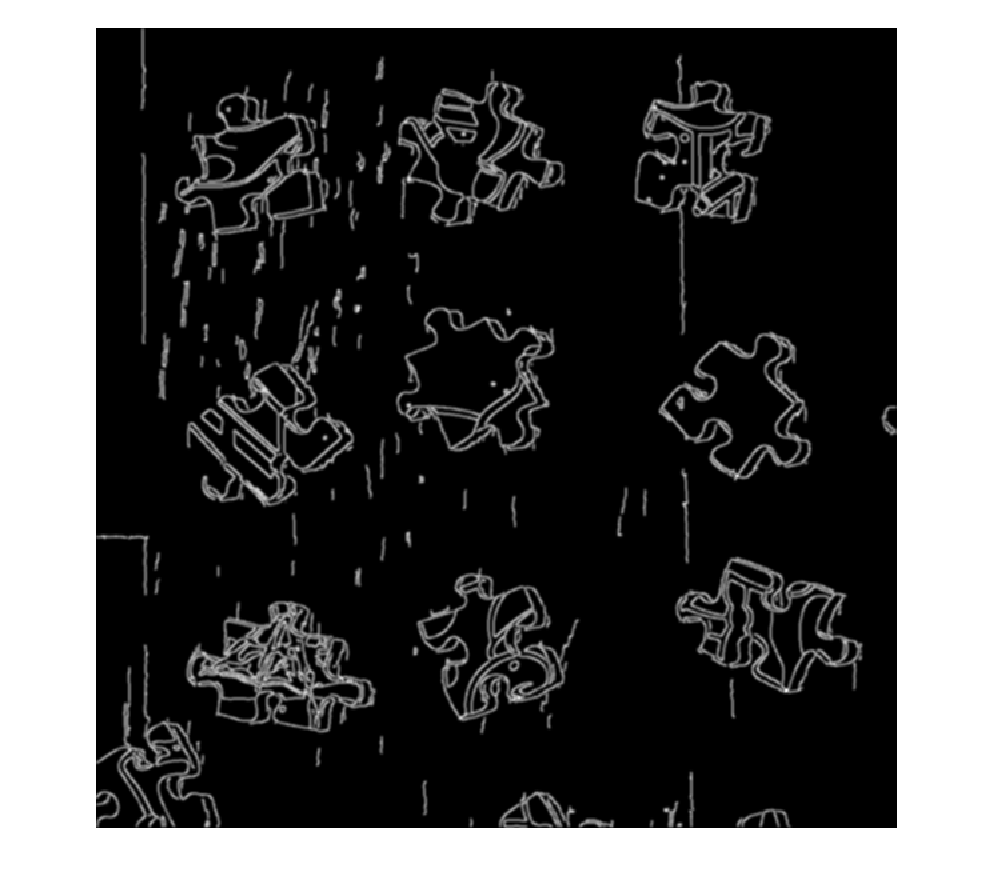

mask = imgaussfilt(double(mask), gaussSigma);
imshow(mask, [])

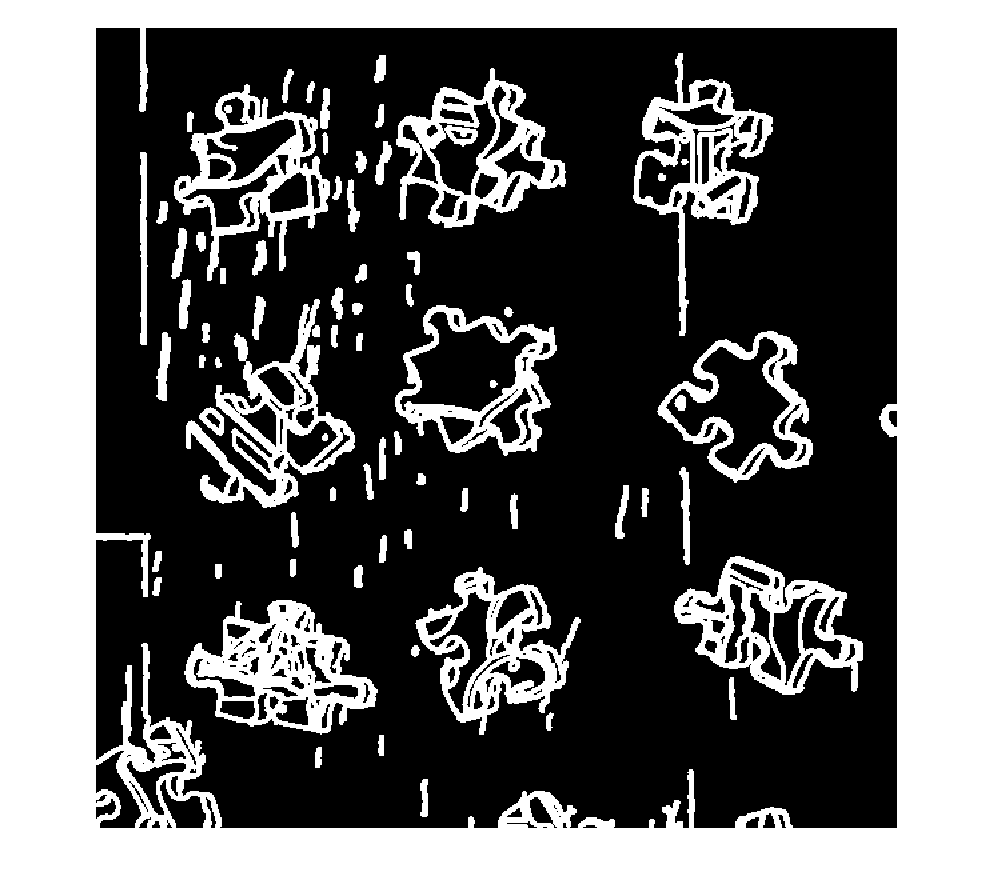

% Um unterbrochene Kanten zu vermeiden, wird mit dem Sensitivity Parameter
% effektiv der Treshold für die Binärisierung ausgeschaltet.
mask = imbinarize(mask, "adaptive", "Sensitivity", 1.0);
imshow(mask, [])

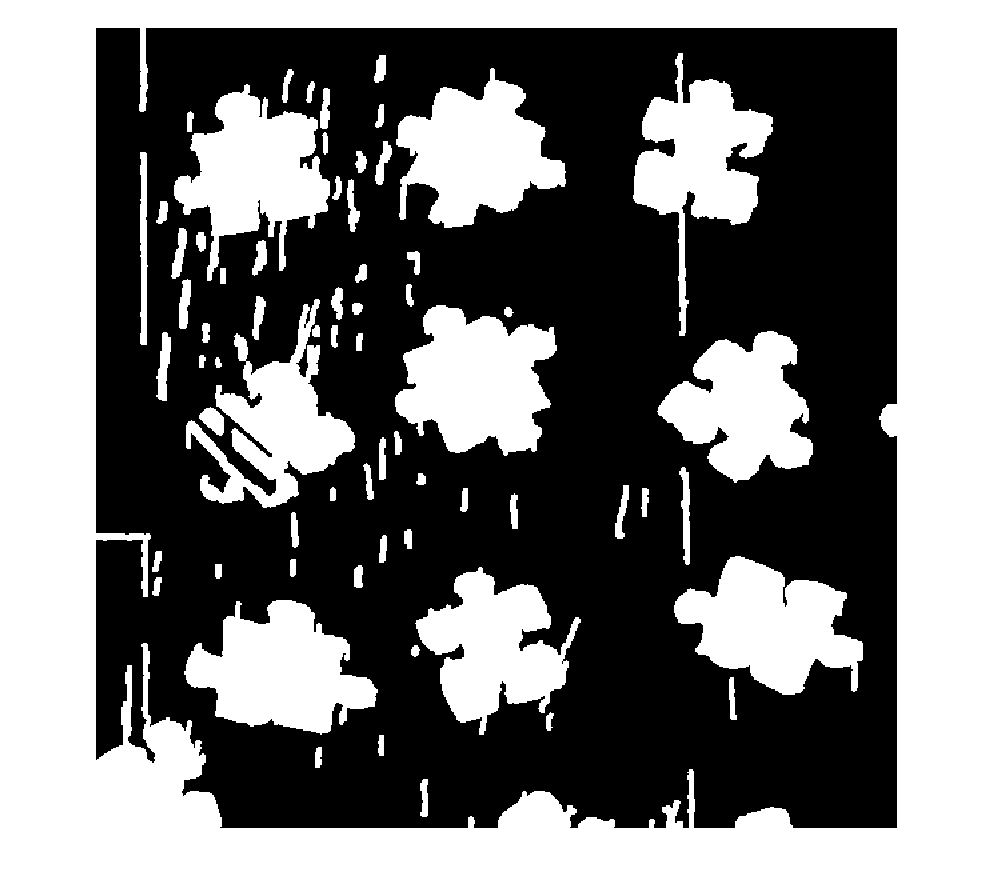

mask = imcomplement(imfill(mask, [1 1]) - mask);
imshow(mask, [])

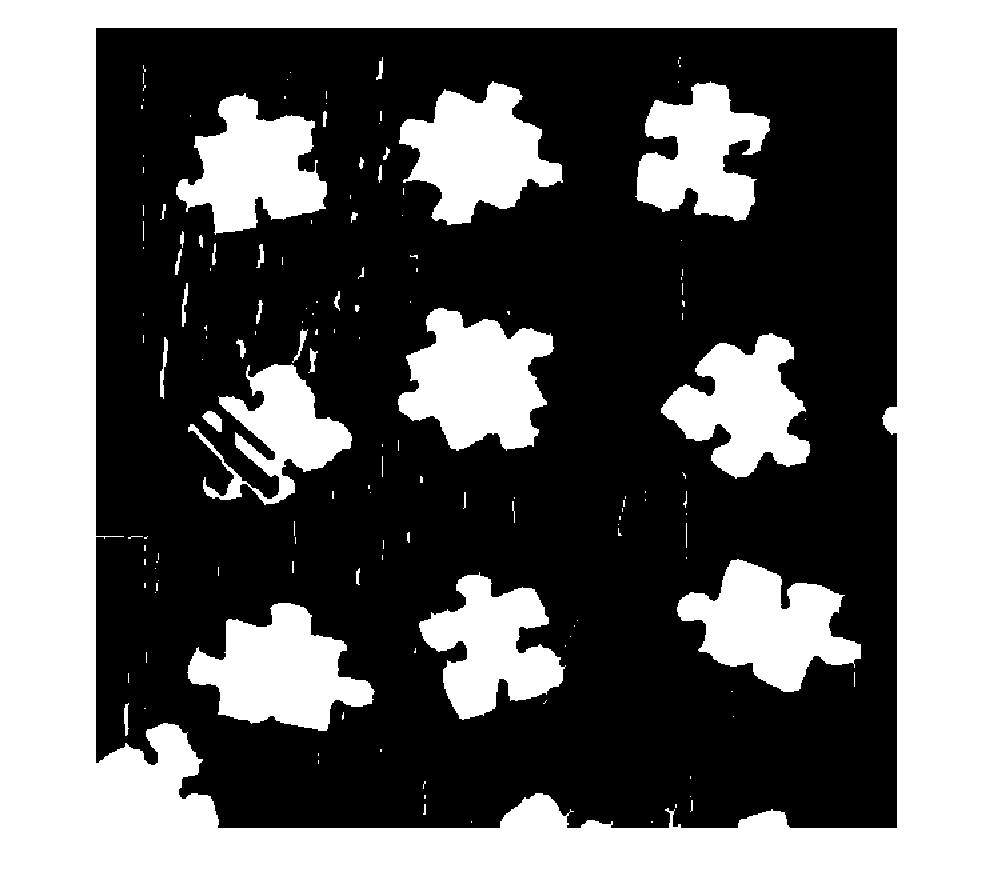

mask = imerode(mask, strel('disk', erodeRadius));
imshow(mask, [])

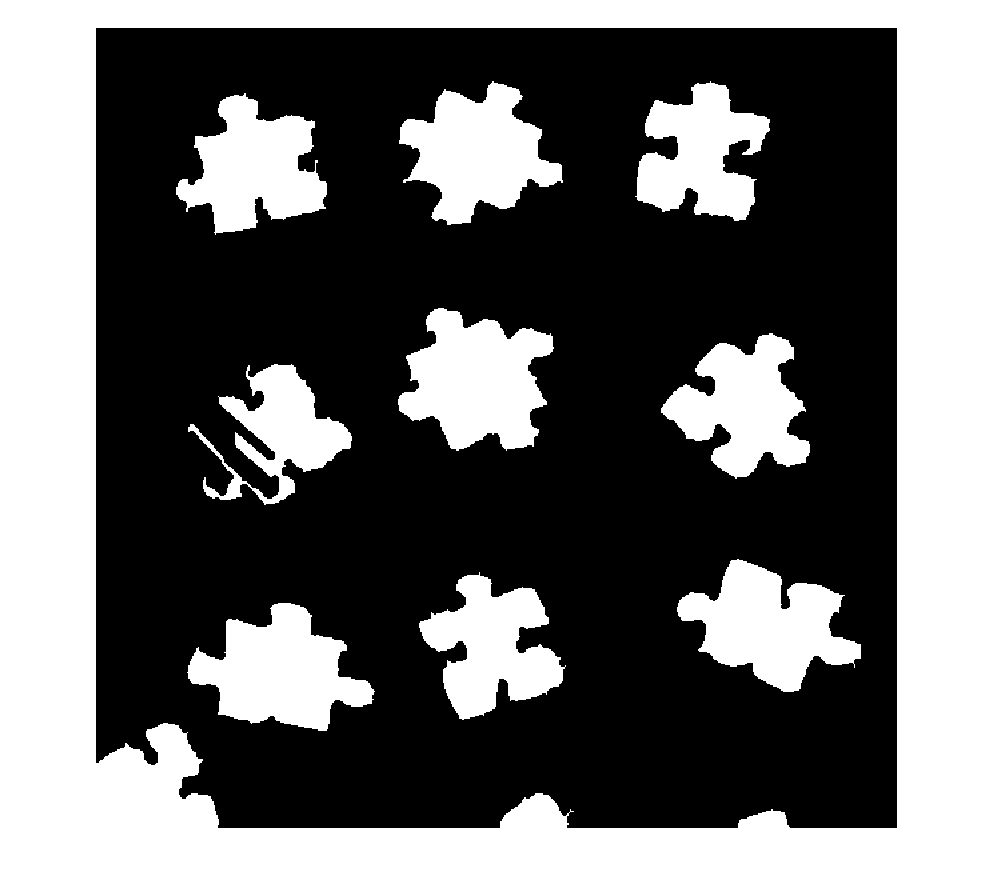

mask = bwareaopen(mask, minAreaSize);
imshow(mask, [])

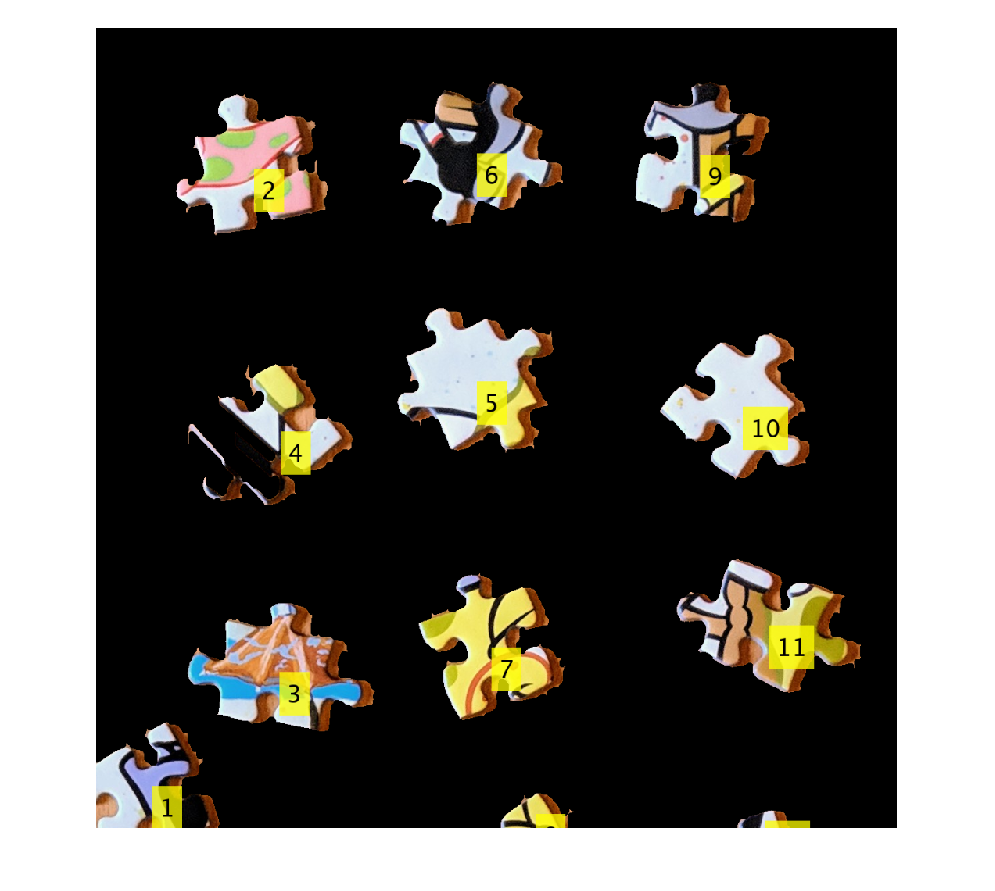

[labeled,labelCount] = bwlabel(mask);

% Zeigt die Anwendung der erzeugten Maske und die Labels
index = 1;
labelOverlayed = piecesRGB .* mask;
while index <= labelCount
    labelOverlayed = insertText(labelOverlayed, ...
        regionprops(labeled==index,'Centroid').Centroid, ...
        index, ...
        "FontSize",36,"BoxOpacity",.75);
    index = index + 1;
end
imshow(labelOverlayed, [])

% Nun wird mit Hilfe der vorher erzeugten Segmentierung über die einzelnen
% Puzzleteile iteriert und mit Hilfe von Feature Detection und Feature
% Matching versucht die richtige Stelle im fertigen Puzzle zu finden.

% Verfügbar: "BRISK", "FAST", "Harris", "MinEigen", "MSER", "ORB", "SURF", "KAZE"
method = "SURF"

method = "SURF"

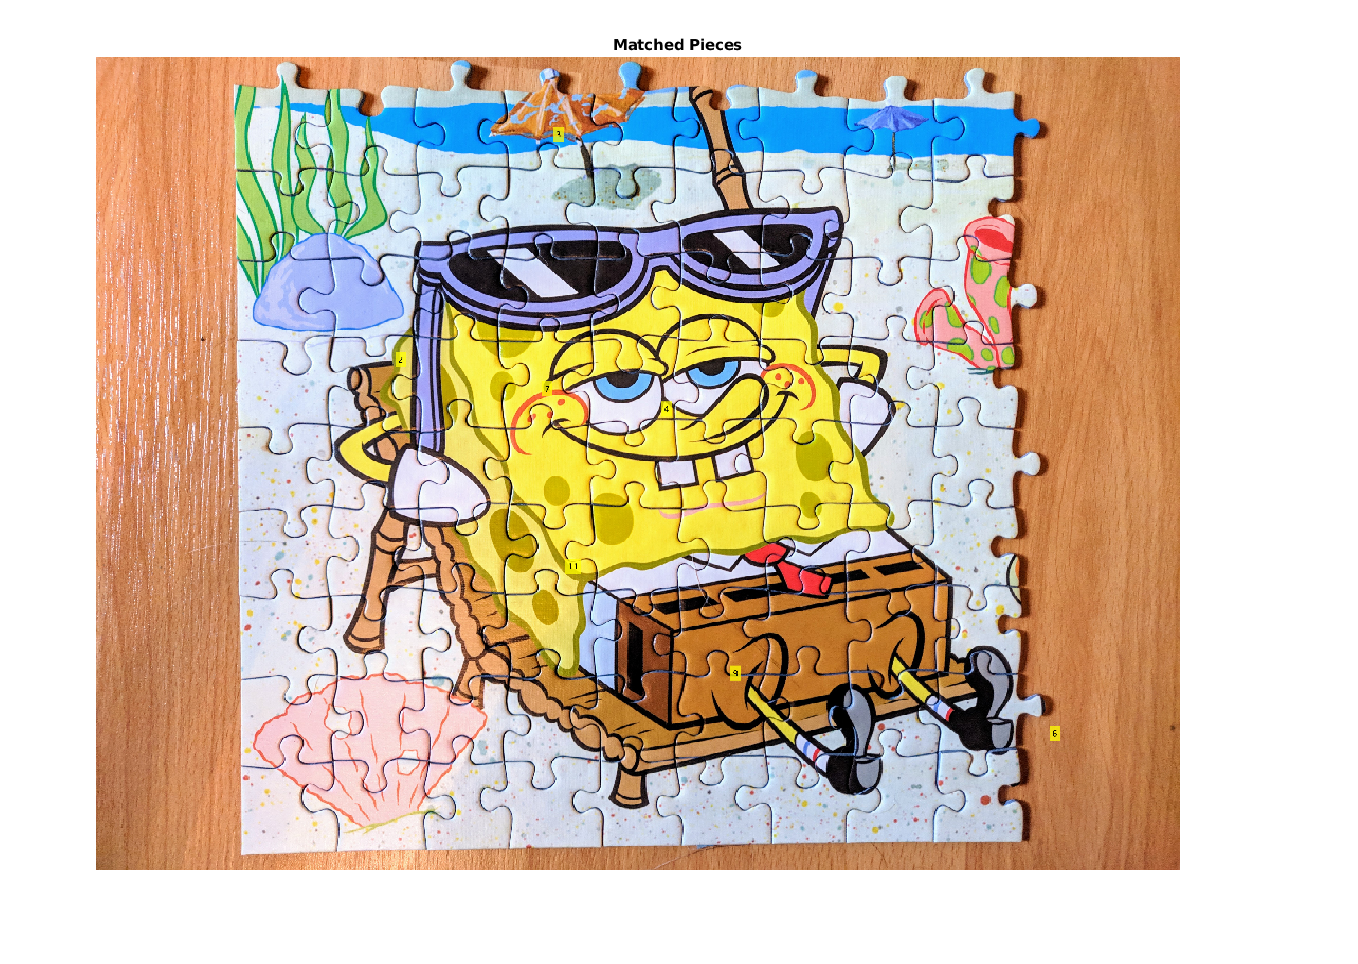


target = rgb2gray(finishedRGB);
% Feature Detection im Bild mit fertigem Puzzle
targetPoints = encodedFeatures(method, target);

figure;
hold on;

index = 1;
while index <= labelCount
    % Bild maskieren (außerhalb aktuellem Puzzleteil = schwarz)
    reference = piecesGray .* (labeled==index);
    % Feature Detection auf dem maskierten Puzzleteil
    referencePoints = encodedFeatures(method, reference);
    
    % Feature Matching zwischen Puzzleteil und fertigem Puzzle
    [matchedReferencePoints, matchedTargetPoints] = matchingPoints( ...
        reference, referencePoints, ...
        target, targetPoints);
    
    if((matchedTargetPoints.length > 2) && (matchedReferencePoints.length > 2))
        try
            % Errechnet eine Transformation zwischen Feature Matches
            [tform, estimatedReferencePoints, estimatedTargetPoints] = ...
                estimateGeometricTransform(matchedReferencePoints, matchedTargetPoints, 'affine');
            % Sucht den Mittelpunkt des Puzzleteils im ursprünglichen
            % (losen) Bild, projeziert diesen mit der errechneten
            % Transformation ins fertige Bild, zeichnet Label ein.
            pieceImageRegion = regionprops(labeled==index,'all');
            finishedRGB = insertText(finishedRGB, ...
                transformPointsForward(tform,pieceImageRegion.Centroid), ...
                index, ...
                "FontSize",36,"BoxOpacity", 0.75);
        catch
            % estimateGeometricTransform kann fehlschlagen, hiermit wird
            % ein Absturz verhindert.
        end
    end
    
    index = index + 1;
end

imshow(finishedRGB);
title('Matched Pieces');
hold off;